% load file and variables data1, regressors1, xdata, ydata
file = matfile('Homework4.mat');
data1 = file.data1;
regressors1 = file.regressors1;
xdata = file.xdata;
ydata = file.ydata;

## 1. The `data1 `variable contains 1,000 data points, and the `regressors1 `variable contains 100 regressors that might explain these data points. (Note: a constant regressor is already included as the 100th regressor.) Consider a linear model that attempts to predict the data as a weighted sum of the regressors. Apply this model to the data, using bootstrapping (500 iterations) to obtain 95% confidence intervals on the parameters of the model. Visualize these confidence intervals on a figure.

iterationsCount = 500;
confidence = .95;

% count of data points (=1000) and count of regressors (=100)
dataPointsCount = size(data1, 1);
regressorsCount = size(regressors1, 2);

% init the parameters estimate
params = zeros(iterationsCount, regressorsCount);

% regressor-column values - x-values (1000 values in each of the 100 regressors), 
% data1 - y-values.
% consider linear model: y = a * x + b; -> data1 = a * rValue + b

% do bootstraping iterationsCount times
for i = 1 : iterationsCount
    
    % prepare random data indices
    % rand(1,n) = [0:1](1x100)
    ix = ceil(dataPointsCount * rand(1, dataPointsCount));
    
    % construct regressor matrix using random indices
    X = regressors1(ix, :);
    
    % estimate parameters
    h = inv(X' * X) * X' * data1(ix);
    
    % record the parameters
    params(i, :) = h;
end

% Calculate 5, 50, 95 percentiles for parameters along the columns of params
% 50th percentile - value, below which 50% of observations may be found
paramsP = prctile(params, [5 50 95], 1);

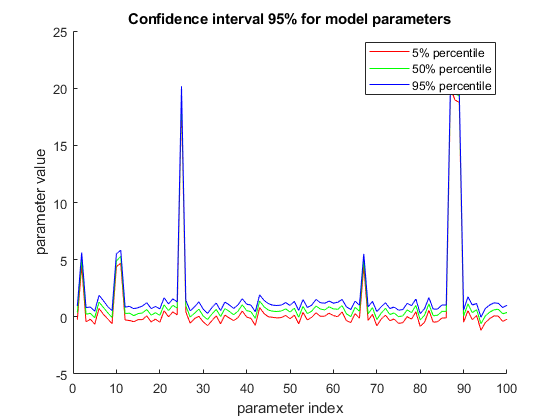

% visualise
figure;
hold on;
xlabel('parameter index')
ylabel('parameter value')
a = plot(paramsP(1, :), 'r-');
b = plot(paramsP(2, :), 'g-');
c = plot(paramsP(3, :), 'b-');

legend([a b c], '5% percentile', '50% percentile', '95% percentile');
title('Confidence interval 95% for model parameters');

## 2. We have 20 subjects and 100 measurements of *x *and *y *from each subject. The `xdata `variable contains the *x*-measurements, and the `ydata `variable contains the *y*-measurements. We want to see whether there is a nonlinear (quadratic) relationship between the *x *variable and the *y *variable. To do this, for each subject, use 10-fold cross-validation to estimate (1) the accuracy of a linear model (*y*= *ax*+ *b*) and (2) the accuracy of a quadratic model (*y *=*ax^*2+*bx *+*c*). Use *R^*2 to quantify accuracy. Make a scatter plot that compares the accuracy of the linear model and the accuracy of the quadratic model (there should be 20 dots on this scatter plot).

% R^2 - the coefficient of determination (is a metric for model accuracy)
% variance - the square of the standard deviation = [sum((xi-xMean)^2) / (n-1)]
% we can ignore the denominator and think of variance 
% as the total squared deviation of a set of data points from their mean

% R^2 - is the percentage of variance explained by a model
% R^2 = 100*(1 - sum((xi - mi)^2) / sum((xi - xMean)^2)),
% where xi - ith data point, mi - model fit for data point di, 
% xMean - mean of data points

% R^2: upper bound = 100%, no lower bound
% R^2 = 100% - the case where a model matches the data exactly
% R^2 = 0% - a model that gets the mean of the data correct and nothing else.

% k-fold cross-validation: divide the data into k parts, 
% 1 part - testing set
% k-1 part - training sets
% the process is repeated for each of the k parts (k times)
% when average results for k experiments

% define the k value for k-fold cross-validation algorithm
k = 10;

% dataPointsCount = 100 (how many measurements), 
% subjectsCount = 20 (how many subjects)
dataPointsCount = size(xdata, 1);
subjectsCount = size(xdata, 2);

% randomly split the data into parts
% as a result - create allix 2D-matrix with indices (parts * indices)
% randomly ordered all data indices, at least one part must have this many data points
% cile() -> to the closest int value
% get a vector of 100 values
ixAll = randperm(dataPointsCount);
% numineach = 100/10 => 10
numineach = ceil(dataPointsCount / k);

% reshape dataPointsCount-vector into matrix 10*10 (k*k)
% NaN(...) - creates an array of NaN values
ixAll = reshape([ixAll NaN(1, k * numineach - dataPointsCount)], k, numineach);

% define R^2 function
computeR2func = @(model, data) 100 * (1 - sum((data - model).^2) / sum((data - mean(data)).^2));

% init R2 result values
R2_linear = zeros(1, subjectsCount);
R2_quadratic = zeros(1, subjectsCount);

% analyze each subject
for subject = 1 : subjectsCount
    
    % perform k-fold cross validation for each subject
    prediction_linear = zeros(dataPointsCount, 1);
    prediction_quadratic = zeros(dataPointsCount, 1);
    
    for part = 1 : k
        
        % compute data indices:
        % indices to use for testing
        ixTest = ixAll(part, :);
        % remove NaN values
        ixTest(isnan(ixTest)) = [];
        % indices to use for training
        ixTrain = setdiff(1 : dataPointsCount, ixTest);  
        
        % set out data for linear model
        % prepare regressor matrices (x) and data (y)
        xTrain = [xdata(ixTrain, subject) ...
            ones(length(ixTrain), 1)];
        yTrain = ydata(ixTrain, subject); 
        
        xTest = [xdata(ixTest, subject) ...
            ones(length(ixTest), 1)];
        yTest = ydata(ixTest, subject); 
        
        % Train and test linear model
        h = inv(xTrain' * xTrain) * xTrain' * yTrain;
        prediction_linear(ixTest) = xTest * h;        
        
        % set out data for quadratic model
        % prepare regressor matrices and data
        xTrain = [xdata(ixTrain, subject).^2 ...
            xdata(ixTrain, subject) ...
            ones(length(ixTrain), 1)];
        yTrain = ydata(ixTrain, subject); 
        
        xTest = [xdata(ixTest, subject).^2 ...
            xdata(ixTest, subject) ...
            ones(length(ixTest), 1)];
        yTest = ydata(ixTest, subject); 
        
        % Train and test quadratic model
        h = inv(xTrain' * xTrain) * xTrain' * yTrain;
        prediction_quadratic(ixTest) = xTest * h;               
    end
    
    % compute accuracy
    R2_linear(subject) = computeR2func(prediction_linear, ydata(:, subject));
    R2_quadratic(subject) = computeR2func(prediction_quadratic, ydata(:, subject));
end

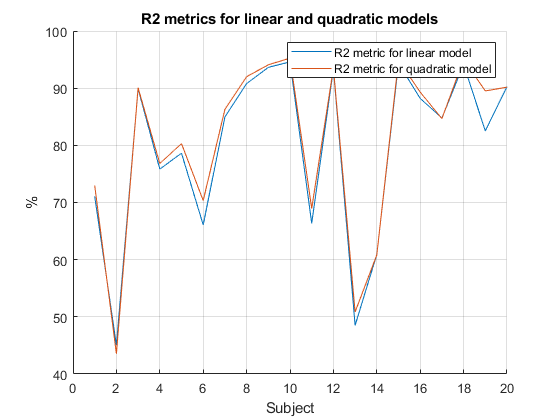

% visualise
% the R2 dependency for each subject for linear and quadratic models
figure;
hold on;
grid;
plot(R2_linear);
plot(R2_quadratic);
title('R2 metrics for linear and quadratic models');
legend('R2 metric for linear model', 'R2 metric for quadratic model');
xlabel('Subject');
ylabel('%')

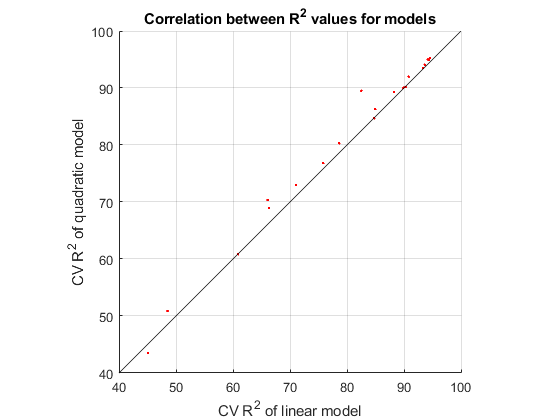

% visualise 
% scatter plot that compares the accuracy of the linear model and the accuracy 
% of the quadratic model (there should be 20 dots on this scatter plot)
% all the values are close to the line
figure;
hold on;
grid;
scatter(R2_linear, R2_quadratic, 'r.');
axis equal square;
ax = axis;
plot(ax(1:2), ax(1:2), 'k-');
xlabel('CV R^2 of linear model');
ylabel('CV R^2 of quadratic model');
% values of R^2 for different models are quite similar -> correlation
% exists
title('Correlation between R^2 values for models');